We want to model the system using Euler-Lagrange modelling. We have two degrees of freedom $\theta_1$ and $\theta_2$.

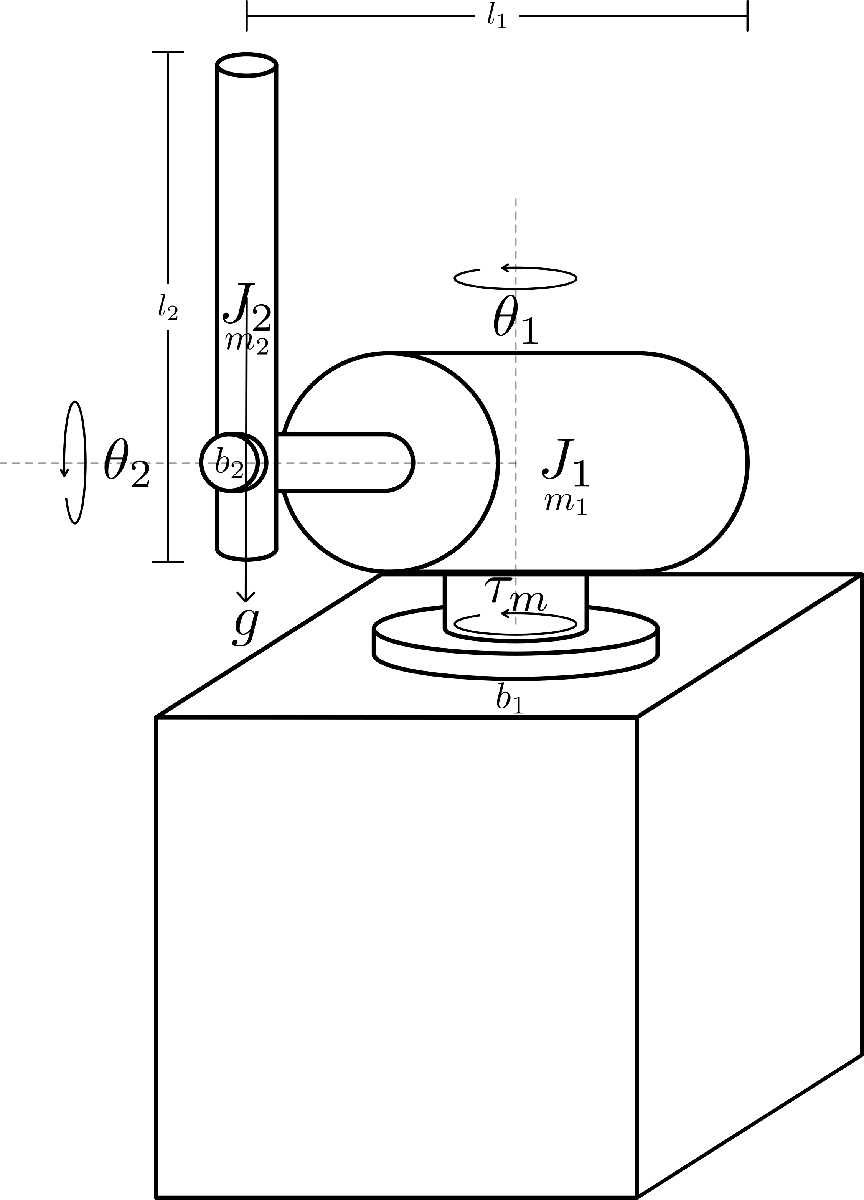

clc; clear; close all;

syms theta_1 theta_2 dtheta_1 dtheta_2 ddtheta_1 ddtheta_2 real
syms m_1 m_2 l_1 l_2 J_1 J_2 real
syms g real
syms b_1 b_2 tau_m real

q = [theta_1; theta_2];
dq = [dtheta_1; dtheta_2];
ddq = [ddtheta_1; ddtheta_2];

The following is from lecture 12 of Modellering

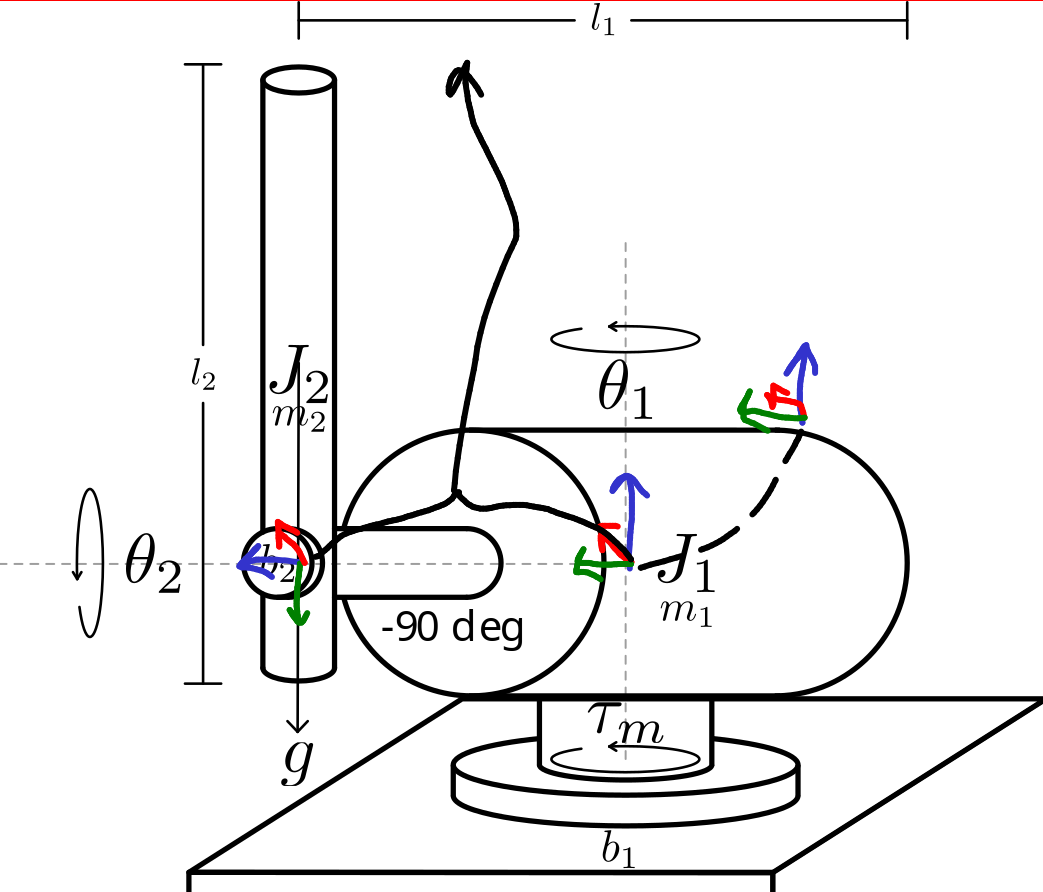

Frame 1 and Frame 2 have intersecting z-axis, so frame 1's x-axis should be the cross product of these two z-axis.

% DH parameters
alpha_0 = 0;
a_0 = 0;
d_0 = 0;

alpha_1 = -90; % angle from z_i to z_i+1 measured about x_i
a_1 = 0; % Offset along i x-axis
d_1 = 0; % Offset along i z-axis

alpha_2 = 0; % degrees
a_2 = 0;
d_2 = l_1/2; % Since we offset along the arm, this is the translation along z_2
% And since l_1 is from the end of the encoder to the joint of the
% pendulum, we will need to divide by 2 (approximately) to go from the
% middle of the encoder (frame 1 origin) to the origin of frame 2

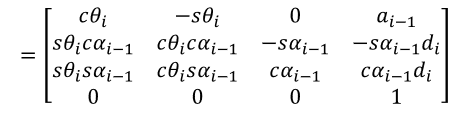

% Transformation matrix for links from DH parameters (L5 robotkinematik)
T_0_1=[              cos(theta_1)              -sin(theta_1)             0                 a_0;
       sin(theta_1)*cosd(alpha_0) cos(theta_1)*cosd(alpha_0) -sind(alpha_0) -sind(alpha_0)*d_1;
       sin(theta_1)*sind(alpha_0) cos(theta_1)*sind(alpha_0)  cosd(alpha_0)  cosd(alpha_0)*d_1;
                               0                          0              0                   1];

T_1_2 = [            cos(theta_2)              -sin(theta_2)             0                 a_1;
       sin(theta_2)*cosd(alpha_1) cos(theta_2)*cosd(alpha_1) -sind(alpha_1) -sind(alpha_1)*d_2;
       sin(theta_2)*sind(alpha_1) cos(theta_2)*sind(alpha_1)  cosd(alpha_1)  cosd(alpha_1)*d_2;
                               0                          0              0                   1];

T_0_2 = T_0_1*T_1_2;

% Position of origo in regards to base frame
p_0 = [0;0;0];
p_0_1 = T_0_1(1:3,4);
p_0_2 = T_0_2(1:3,4);

% Position of link center in regards to base frame
p_0_c1 = p_0_1; % Center of mass is already at rotation point
p_0_c2 = T_0_2(1:3, 1:3)*[0; -l_2/2; 0]+p_0_2;

% Orientation of z-axis in regards to base frame
z_0 = [0;0;1];
z_0_1 = T_0_1(1:3, 3);
z_0_2 = T_0_2(1:3, 3);


54)58)

% Jacobians for each joint (L12 modellering, and L10 robotkinematik)
J_P_1 = [cross(z_0, (p_0_c1 - p_0)) [0;0;0]];
J_P_2 = [cross(z_0, (p_0_c2 - p_0)) cross(z_0_1, (p_0_c2 - p_0_1))];
% We will also need to find the orientational Jacobian

% To find the full expression of kinetic energy
J_O_1 = [[0;0;1] [0;0;0]]; % No joint affects the z-axis orientation of frame 1. The matrix is [z_0, 0]
J_O_2 = [[0;0;1] T_0_1(1:3, 3)]; % Only joint 1 affects the z-axis of frame 2. The matrix is [z_0, z_0_1]

% To find the B-matrix, we will also need the inertia tensor of each link
% expressed in their own local frame.
% NEEED FILLING OUT!!

% Since we know, that E_kin can be expressed using both the B-matrix, and
% the Jacobians, we need to isolate the B-matrix from the equation at the
% top of this section.
% B-matrix (L12 modellering)
B = m_1*J_P_1'*J_P_1 + m_2*J_P_2'*J_P_2 + J_O_1'*T_0_1(1:3, 1:3)*

$$B = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & \sigma_{1}\\ \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{\left(\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\right)}^{2}+m_{2}\,{\left(\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\right)}^{2} \end{array}$$

E_kin_0 = simplify(1/2 * dq' * B * dq)

$$E\_kin\_0 = \frac{m_{2}\,{\left({\mathrm{dtheta}}_{1}+{\mathrm{dtheta}}_{2}\right)}^{2}\,\left({l_{1}}^{2}+{l_{2}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\right)}{8}$$

% The g vector is how gravity affects in either direction from the base
% frame. The gravity only affects the system in the base frames z-axis
% going downards. So that is
g_direction = [0; 0; -g];
E_pot_0 = -(m_1*g_direction'*p_0_c1 + m_2*g_direction'*p_0_c2)

$$E\_pot\_0 = \frac{g\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)}{2}$$

## Deriviation from corialis forces

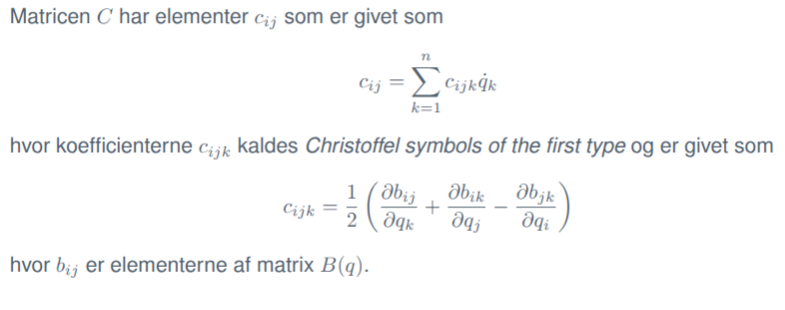

n = 2;
C = sym(zeros(n,n));
for i = 1:n
    for j = 1:n
        for k = 1:n
            c_ijk = 1/2 * (diff(B(i,j), q(k)) + diff(B(i,k), q(j)) - diff(B(j,k), q(i)));
            C(i,j) = C(i,j) + c_ijk * dq(k);
        end
    end
end

A Dynamical model for a robot can then be described as

We only need to calculate g(q), which is derived from E_pot as follows

g_q = [diff(E_pot_0, q(1)); diff(E_pot_0, q(2))];

% The tau vector is all generalised forces applied to the system. So that
% is input torque and friction
force_vec = [tau_m-b_1*dtheta_1; -b_2*dtheta_2] % Only joint 1 has a torque applied to it

$$force\_vec = \left(\begin{array}{c} \tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\\ -b_{2}\,{\mathrm{dtheta}}_{2} \end{array}\right)$$


%Thus
sys1 = B*ddq + C*dq + g_q == force_vec

$$sys1 = \begin{array}{l} \left(\begin{array}{c} {\mathrm{ddtheta}}_{1}\,\sigma_{1}-{\mathrm{dtheta}}_{2}\,\left({\mathrm{dtheta}}_{2}\,\left(\sigma_{4}-\sigma_{3}\right)+{\mathrm{dtheta}}_{1}\,\sigma_{2}\right)+{\mathrm{ddtheta}}_{2}\,\sigma_{1}-{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,\sigma_{2}=\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\\ \sigma_{2}\,{{\mathrm{dtheta}}_{1}}^{2}+\left(\frac{\sigma_{3}}{2}-\frac{\sigma_{4}}{2}\right)\,{{\mathrm{dtheta}}_{2}}^{2}+{\mathrm{ddtheta}}_{1}\,\sigma_{1}+{\mathrm{ddtheta}}_{2}\,\sigma_{1}-\frac{g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}=-b_{2}\,{\mathrm{dtheta}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{\sigma_{5}}^{2}+m_{2}\,{\sigma_{6}}^{2}\\ \sigma_{2}=\frac{\sigma_{4}}{2}-\frac{\sigma_{3}}{2}\\ \sigma_{3}=l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sigma_{5}\\ \sigma_{4}=l_{2}\,m_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sigma_{6}\\ \sigma_{5}=\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\\ \sigma_{6}=\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2} \end{array}$$

% We can isolate ddq, to get the following
ddq_calculated = inv(B)*(force_vec-C*dq-g_q);

% Next we setup the state and system vectors
% State space vectors
x = [q; dq];

% System vectors
dx = [dq; ddq];

% Input vector
tau_vec = [tau_m; 0]; % Only joint 1 is affected by torque

% The state space system is then
ss_sys = simplify([dq; ddq_calculated] + [0 0; 0 0; inv(B)]*force_vec*tau_m) % Der er nogle uenelighedstegn her... det er ikke for godt

$$ss\_sys = \left(\begin{array}{c} {\mathrm{dtheta}}_{1}\\ {\mathrm{dtheta}}_{2}\\ \tau_{m}\,\left(\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\right)\,\infty +\left(-\frac{m_{2}\,\sin\left(2\,\theta_{2}\right)\,{{\mathrm{dtheta}}_{2}}^{2}\,{l_{2}}^{2}}{4}-\frac{{\mathrm{dtheta}}_{1}\,m_{2}\,\sin\left(2\,\theta_{2}\right)\,{\mathrm{dtheta}}_{2}\,{l_{2}}^{2}}{4}+\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\right)\,\infty \\ \left(\frac{m_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}\,{l_{2}}^{2}}{4}-\frac{m_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)\,{{\mathrm{dtheta}}_{2}}^{2}\,{l_{2}}^{2}}{4}-b_{2}\,{\mathrm{dtheta}}_{2}+\frac{g\,m_{2}\,\sin\left(\theta_{2}\right)\,l_{2}}{2}\right)\,\infty -b_{2}\,{\mathrm{dtheta}}_{2}\,\tau_{m}\,\infty \end{array}\right)$$

## Lagrangian from robotic kinematics

% Now we can calculate the lagrangian
L = simplify(E_kin_0 - E_pot_0)

$$L = \frac{m_{2}\,{\left({\mathrm{dtheta}}_{1}+{\mathrm{dtheta}}_{2}\right)}^{2}\,\left({l_{1}}^{2}+{l_{2}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\right)}{8}-\frac{g\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)}{2}$$

qL_1 = simplify(diff(L, q(1)));
qL_2 = simplify(diff(L, q(2)));
dqL_1 = simplify(diff(L, dq(1)));
dqL_2 = simplify(diff(L, dq(2)));
% d/dt of dqL(i) using chain rule
dqL1_t = simplify(diff(dqL_1, theta_1)*dtheta_1 + diff(dqL_1, theta_2)*dtheta_2 + diff(dqL_1, dtheta_1)*ddtheta_1 + diff(dqL_1, dtheta_2)*ddtheta_2);

dqL2_t = simplify(diff(dqL_2, theta_1)*dtheta_1 + diff(dqL_2, theta_2)*dtheta_2 + diff(dqL_2, dtheta_1)*ddtheta_1 + diff(dqL_2, dtheta_2)*ddtheta_2);

dqL_t = [dqL1_t; dqL2_t];
qL = [qL_1; qL_2];

% Non-conservative forces
% Both the pendulum and the motor-stick will be affected by _some_
% friction.
% The motor stick will also be affected by the motor-torque, that is
% inputted to the system.
syms b_1 b_2 tau_m
Q = [-b_1 * dtheta_1 + tau_m;
     -b_2 * dtheta_2];

sys0 = Q == dqL_t - qL

$$sys0 = \begin{array}{l} \left(\begin{array}{c} \tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}=\sigma_{3}+\sigma_{2}+\sigma_{1}\\ -b_{2}\,{\mathrm{dtheta}}_{2}=\sigma_{3}+\sigma_{2}-\frac{{l_{2}}^{2}\,m_{2}\,\sin\left(2\,\theta_{2}\right)\,{\left({\mathrm{dtheta}}_{1}+{\mathrm{dtheta}}_{2}\right)}^{2}}{8}-\frac{g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{dtheta}}_{2}\,{l_{2}}^{2}\,m_{2}\,\sin\left(2\,\theta_{2}\right)\,\left(2\,{\mathrm{dtheta}}_{1}+2\,{\mathrm{dtheta}}_{2}\right)}{8}\\ \sigma_{2}=\frac{{\mathrm{ddtheta}}_{2}\,m_{2}\,\left({l_{1}}^{2}+{l_{2}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\right)}{4}\\ \sigma_{3}=\frac{{\mathrm{ddtheta}}_{1}\,m_{2}\,\left({l_{1}}^{2}+{l_{2}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\right)}{4} \end{array}$$

sys01 = isolate(sys0(1), ddtheta_1*m_1)

Error using sym/isolate (line 108)
Unable to isolate 'ddtheta_1*m_1' because the equation has no solution.


% Extract M matrix and rhs vector
vars = [ddtheta_1; ddtheta_2];
[M, rhs] = equationsToMatrix(sys0, vars);

% Solve for accelerations
ddq = simplify(M \ rhs);

ddtheta_1_sol = ddq(1)
ddtheta_2_sol = ddq(2)

We will first create kinetic and potential energy for the pendulum (system 2) and for the motor-stick (system 1)

## System 1

% The motor stick does not have any potential energy assigned to it.
% It _is_ affected by gravity, but since gravity does not influence its
% movement path (that being in the x-/y-plane), it is not accounted for
E_pot1 = 0;

% Since it is a rotating system, it only has a  rotary kinetic energy, and
% no translatoric kinetic energy
E_kin1 = 1/2 * J_1 * dtheta_1^2;


## System 2

% The pendulum is affected by gravity, and thus the potential energy
% reflects that. The reference point (point-zero) is set at the swing-axis,
% therefore the potential energy is dependent on the pendulums distance
% from said reference point.
% 0 degrees is also defined now. It is defined to be when the pendulum
% hangs downwards, thus making 180 degrees the point where it stands
% straight up.
% Then the potential energy is
E_pot2 = -m_2*l_2*g*cos(theta_2);

% The pendulum has both a rotary and a translatoric kinetic energy. The
% rotary kinetic energy is only dependent on the pendulum itself, but the
% translatoric kinetic energy is dependent on both the motor-stick and the
% pendulum's rotary speed (depending on the axis)
% For the up-down axis, z, the pendulums translatoric kinetic energy will
% be
E_kin2_z = 1/2 * m_2 * (l_2*dtheta_2*sin(theta_2))^2;

% The x-/y-axis translatoric energy is dependent on the motor-sticks speed
% at the pendulum's swing-axis. This is calculated as
v_1 = l_1 * dtheta_1;

% And thus the translatoric kinetic energy in the x-/y-axis for the
% pendulum is
E_kin2_xy = 1/2 * m_2 * (v_1 + l_2 * dtheta_2 * cos(theta_2))^2;

% And the rotary kinetic energy for the pendulum follows the same structure
% as that for the motor-stick. Thus being
E_kin2_rot = 1/2 * J_2 * dtheta_2^2;

% Finally, the kinetic energy for the pendulum is
E_kin2 = E_kin2_rot + E_kin2_xy + E_kin2_z;


## Whole system

% We can now combine the energies of system 1 and system 2 to form the
% system as a whole
E_pot = E_pot1 + E_pot2;

E_kin = E_kin1 + E_kin2;


## Lagrangian

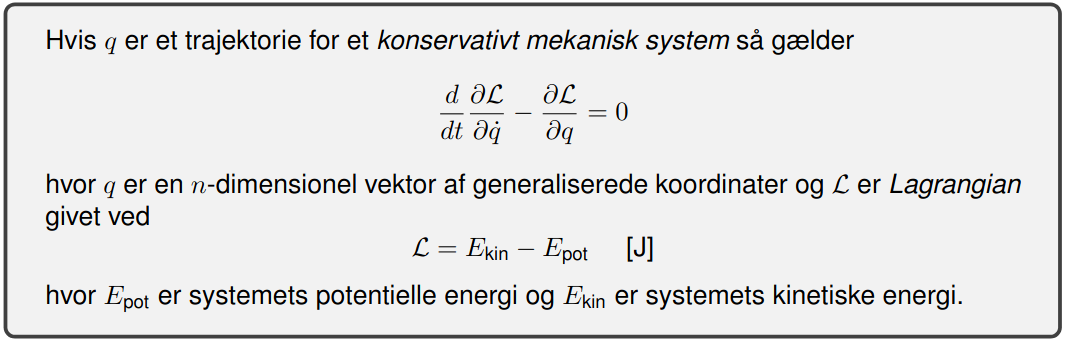

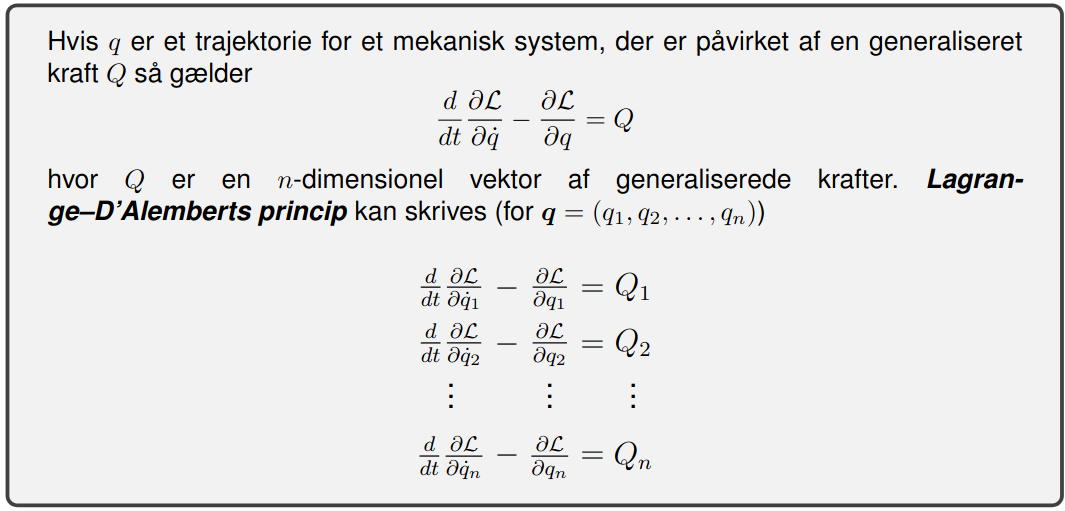

We will now do the Euler-Lagrange modelling following the above method

% Lagrangian
Lagrange = E_kin - E_pot;

qL1 = simplify(diff(Lagrange, q(1)))
qL2 = simplify(diff(Lagrange, q(2)))
dqL1 = simplify(diff(Lagrange, dq(1)))
dqL2 = simplify(diff(Lagrange, dq(2)))
qL = [qL1; qL2];
% We will now need to differentiate dqL1 and dqL2 with t. This is done
% manually (as I have not set it up properly to do it by MATLAB...)


$$\frac{d}{\textrm{dt}}*\textrm{dqL1}=J_1 \ddot{\;\theta_1 } +l_1 m_2 \left(\ddot{\;\theta_1 } l_1 -\ddot{\;\theta_2 } l_2 \;\dot{\;\theta_2 \;} \sin \left(\theta_2 \right)\right)$$



$$\frac{d}{\textrm{dt}}*\textrm{dqL2}=\ddot{\;\theta_2 } m_2 l_2^2 -\ddot{\theta_1 } l_1 m_2 \dot{\;\theta_2 } \sin \left(\theta_2 \right)l_2 +J_2 \ddot{\;\theta_2 }$$


% Now we just write it to matlab code, so that we can use it
dqL1_t = J_1 * ddtheta_1 + l_1 * m_2 * (ddtheta_1 * l_1 - ddtheta_2 * l_2 * dtheta_2 * sin(theta_2));
dqL2_t = J_2 * ddtheta_2 + ddtheta_2 * m_2 * l_2^2 - ddtheta_1 * l_1 * m_2 * dtheta_2 * sin(theta_2);

dqL_t = [dqL1_t; dqL2_t];

% Non-conservative forces
% Both the pendulum and the motor-stick will be affected by _some_
% friction.
% The motor stick will also be affected by the motor-torque, that is
% inputted to the system.
syms b_1 b_2 tau_m
Q = [-b_1 * dtheta_1 + tau_m;
     -b_2 * dtheta_2];

% Finally, we can calculate the system's movement-equations using the
% method from the pictures above
sys = Q == dqL_t - qL
sys1 = isolate(simplify(sys(1)), J_1*ddtheta_1) % Motor stick
sys2 = isolate(simplify(sys(2)), J_2*ddtheta_2) % Pendulum
% Noget gået galt, da ddtheta både 1 og 2 indgår på begge sidder
% af lighedstegnene.

## Time domain models

We now try to write up state space models for the system, that can later be converted to transfer functions.

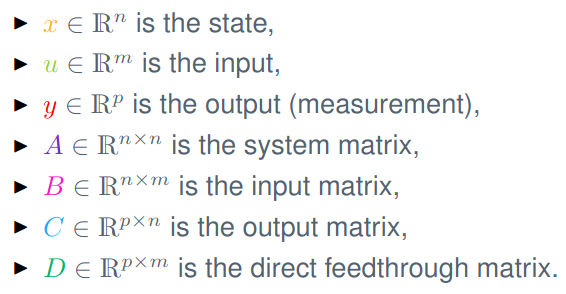

We will want to use the torque $\tau_m$ as an input and get the angular velocity of the pendulum $\dot{\theta_2 }$ as an output. We want this to be zero. We also want the angle $\theta_2$ to be 180 degrees (but this is for another time...)

% State space vectors
x_1 = [theta_1; dtheta_1];
x_2 = [theta_2; dtheta_2];
x = [x_1; x_2];

% System vectors
dx_1 = [dtheta_1; ddtheta_1];
dx_2 = [dtheta_2; ddtheta_2];
dx = [dx_1; dx_2];

% A matrix (found by isolating ddtheta in the system formulars)
sys1_A = isolate(sys1, ddtheta_1)
sys2_A = isolate(sys2, ddtheta_2)
%A = [0 1 0 0;
 %    0 -b_1/(m_2*l_1^2+J_1) %sin(theta_2)???? %hvordan pokker skal jeg opdele dtheta_2 udtrykket?]